dcl_init()
rng(1)

#### **Experiment 5-1)**

- As instructed in the manual, the dcl_init.m file is saved with the following name.

#### **Experiment 5-2)**

**Part 1) Bit Generation**

%pkt_size = 1e5;
%M = 4;
b_tx = bit_gen(pkt_size, M)

b_tx =      0     0
     1     1
     0     0
     0     0
     0     1
     0     1
     0     1
     0     0
     0     0
     1     0


**Part 2) Bit to Symbol Mapping**

%% Step 1
%k = log2(M);
b_gray = gray_code(k)

b_gray =      0     0
     0     1
     1     1
     1     0


 
sym_idx = zeros(pkt_size,1);
for i=1:length(b_tx)
    temp = b_tx(i,:);
    for j=0:length(b_gray)-1
        if b_gray(j+1,:) == temp
            sym_idx(i) = j;
            break;
        end
    end
end
sym_idx

sym_idx =      0
     2
     0
     0
     1
     1
     1
     0
     0
     3


%% Step 2

disp("Gray Encoding")

Gray Encoding


sym_idx_gray = sym_encoding(b_tx,1)

sym_idx_gray =      0
     2
     0
     0
     1
     1
     1
     0
     0
     3



disp("Normal Encoding")

Normal Encoding


sym_idx_bin = sym_encoding(b_tx,0)

sym_idx_bin =      0
     3
     0
     0
     1
     1
     1
     0
     0
     2


%% Step 3

mod_values = constellation(M,modulation);
mod_sym_bin = zeros(pkt_size,1);
for i=1:length(sym_idx)
    mod_sym_bin(i) = mod_values(sym_idx_bin(i)+1);   
end
mod_sym_bin

mod_sym_bin =    1.0000 + 0.0000i
  -0.0000 - 1.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   0.0000 + 1.0000i
   0.0000 + 1.0000i
   0.0000 + 1.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
  -1.0000 + 0.0000i




mod_sym_gray = zeros(pkt_size,1);
for i=1:length(sym_idx)
    mod_sym_gray(i) = mod_values(sym_idx_gray(i)+1);   
end
mod_sym_gray

mod_sym_gray =    1.0000 + 0.0000i
  -1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   0.0000 + 1.0000i
   0.0000 + 1.0000i
   0.0000 + 1.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
  -0.0000 - 1.0000i


**Part 3) Transmitive Signal Waveform**

tx_smpl_bin =pulse_modulation(sym_idx_bin, modulation, M, fs, smpl_per_symbl, pulse_name , 'kron', 0)

tx_smpl_bin =    0.0000 + 0.0000i
   0.1508 + 0.0000i
   0.3015 + 0.0000i
   0.4523 + 0.0000i
   0.6030 + 0.0000i
   0.4523 + 0.0000i
   0.3015 + 0.0000i
   0.1508 + 0.0000i
   0.0000 + 0.0000i
  -0.0000 - 0.1508i


t = 1:smpl_per_symbl*pkt_size;
subplot(2,1,1);
plot(t,real(tx_smpl_bin),'blue');hold on;
plot(t,imag(tx_smpl_bin),'red');
title("Real & Imag Part of tx smpl binary encoding");
legend("real(tx_smpl)","imag(tx_smpl)");
xlabel('Samples');
hold off;
tx_smpl_gray =pulse_modulation(sym_idx_gray, modulation, M, fs, smpl_per_symbl, pulse_name , 'kron', 0)

tx_smpl_gray =    0.0000 + 0.0000i
   0.1508 + 0.0000i
   0.3015 + 0.0000i
   0.4523 + 0.0000i
   0.6030 + 0.0000i
   0.4523 + 0.0000i
   0.3015 + 0.0000i
   0.1508 + 0.0000i
   0.0000 + 0.0000i
  -0.1508 + 0.0000i


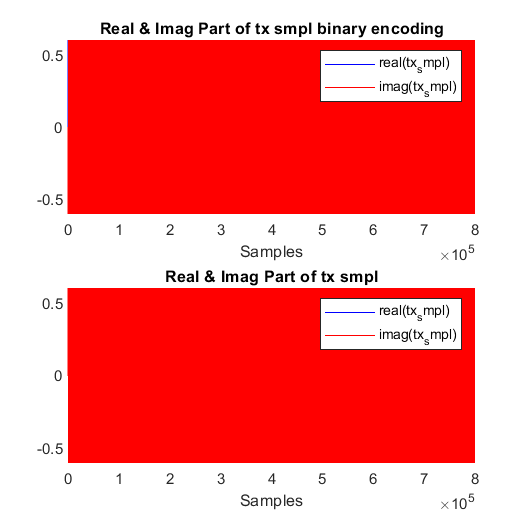

t = 1:smpl_per_symbl*pkt_size;
subplot(2,1,2)
plot(t,real(tx_smpl_gray),'blue');hold on;
plot(t,imag(tx_smpl_gray),'red');
title("Real & Imag Part of tx smpl");
legend("real(tx_smpl)","imag(tx_smpl)");
xlabel('Samples');

#### **Experiment 5-3)**

**Part 1)**

chnl_delay_in_smpl = 0;
tx_smpl_delayed_bin = [zeros(chnl_delay_in_smpl,1);tx_smpl_bin];
tx_smpl_delayed_gray = [zeros(chnl_delay_in_smpl,1);tx_smpl_gray];

**Part 2)**

chnl_phase_offset = 0;
phase_difference = exp(1i*chnl_phase_offset);
rx_smpl_bin = tx_smpl_delayed_bin * phase_difference;
rx_smpl_gray = tx_smpl_delayed_gray * phase_difference;

**Part 3) AWGN Channel Simulation**

%% Step 1

%M = 4;
%modulation = 'psk';
[~, Es_avg] = constellation(M, modulation);
Eb = Es_avg / log2(M) ;
N0 = Eb / (10^(3/10));
var_noise = N0;

%% Step 2

noise_smpl_bin = sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_bin),1) + 1i * sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_bin),1);
noise_smpl_gray = sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_gray),1) + 1i * sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_gray),1);
rx_smpl_bin_noise = rx_smpl_bin + noise_smpl_bin;
rx_smpl_gray_noise = rx_smpl_gray + noise_smpl_gray;

#### Experiment 5-4) Modulation Receiver Implementation

Section 5)

% rx_smpl_bin = rx_smpl_bin_noise;
% rx_smpl_gray = rx_smpl_gray_noise;
% modulation = 'psk';
% M = 4;
% fs = 10e6;
% smpl_per_symbl = 8;
% pulse_name = 'triangular';
rx_mode = 2;
[det_sym_idx_bin, rx_sym_bin] = pulse_demodulation(pkt_size,rx_smpl_bin, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode, 0);
[det_sym_idx_gray, rx_sym_gray] = pulse_demodulation(pkt_size,rx_smpl_gray, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode, 0);

Section 6)

b_binary = de2bi(0:M-1,k,'left-msb');
det_bit_bin = zeros(pkt_size,k);
for i=1:pkt_size
    det_bit_bin(i,:) = b_binary(det_sym_idx_bin(i)+1,:);
end
det_bit_bin

det_bit_bin =      0     0
     1     1
     0     0
     0     0
     0     1
     0     1
     0     1
     0     0
     0     0
     1     0



det_bit_gray = zeros(pkt_size,k);
for i=1:pkt_size
    det_bit_gray(i,:) = b_gray(det_sym_idx_gray(i)+1,:);
end
det_bit_gray

det_bit_gray =      0     0
     1     1
     0     0
     0     0
     0     1
     0     1
     0     1
     0     0
     0     0
     1     0


Section 7)

sym_erros_bin = ~(det_sym_idx_bin == sym_idx_bin);
ser_bin = sum(sym_erros_bin)/length(sym_idx_bin);
bit_errors = ~(det_bit_bin == b_tx);
ber_bin = sum(bit_errors,'all')/(pkt_size*k);
ser_bin

ser_bin = 0

ber_bin

ber_bin = 0


sym_erros_gray = ~(det_sym_idx_gray == sym_idx_gray);
ser_gray = sum(sym_erros_gray)/length(sym_idx_gray);
bit_errors = ~(det_bit_gray == b_tx);
ber_gray = sum(bit_errors,'all')/(pkt_size*k);
ser_gray

ser_gray = 0

ber_gray

ber_gray = 0

**Experiment 5-5)**

Section 1)

snr_min = 0;
snr_max = 10;
snr_step = 0.5;
snr_values = snr_min:snr_step:snr_max;
ser_bin_vals = zeros(length(snr_values),1);
ber_bin_vals = zeros(length(snr_values),1);
ser_gray_vals = zeros(length(snr_values),1);
ber_gray_vals = zeros(length(snr_values),1);

for i = 1:length(snr_values)
    temp_received_signal_bin = rx_smpl_bin;
    temp_received_signal_gray = rx_smpl_gray;
    snr_val = snr_values(i);
    N0 = Eb / (10^(snr_val/10));
    var_noise = N0;
    
    noise_smpl_bin = sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_bin),1) + 1i * sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_bin),1);
    noise_smpl_gray = sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_gray),1) + 1i * sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_gray),1);
    rx_smpl_bin_noise =  temp_received_signal_bin + noise_smpl_bin;
    rx_smpl_gray_noise =  temp_received_signal_gray + noise_smpl_gray;
    
%     rx_smpl_bin = rx_smpl_bin_noise;
%     rx_smpl_gray = rx_smpl_gray_noise;
%     modulation = 'psk';
%     M = 4;
%     fs = 10e6;
%     smpl_per_symbl = 8;
%     pulse_name = 'triangular';
%     rx_mode = 2;
    [det_sym_idx_bin, rx_sym_bin] = pulse_demodulation(pkt_size,rx_smpl_bin_noise, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode, 0);
    [det_sym_idx_gray, rx_sym_gray] = pulse_demodulation(pkt_size,rx_smpl_gray_noise, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode, 0);

    b_binary = de2bi(0:M-1,k,'left-msb');
    det_bit_bin = zeros(pkt_size,k);
    for j=1:pkt_size
        det_bit_bin(j,:) = b_binary(det_sym_idx_bin(j)+1,:);
    end
    
    det_bit_gray = zeros(pkt_size,k);
    for j=1:pkt_size
        det_bit_gray(j,:) = b_gray(det_sym_idx_gray(j)+1,:);
    end
    
    sym_erros_bin = ~(det_sym_idx_bin == sym_idx_bin);
    ser_bin = sum(sym_erros_bin)/length(sym_idx_bin);
    bit_errors = ~(det_bit_bin == b_tx);
    ber_bin = sum(bit_errors,'all')/(pkt_size*k);
   
    sym_erros_gray = ~(det_sym_idx_gray == sym_idx_gray);
    ser_gray = sum(sym_erros_gray)/length(sym_idx_gray);
    bit_errors = ~(det_bit_gray == b_tx);
    ber_gray = sum(bit_errors,'all')/(pkt_size*k);

    ser_bin_vals(i) = ser_bin;
    ser_gray_vals(i) = ser_gray;
    ber_bin_vals(i) = ber_bin;
    ber_gray_vals(i) = ber_gray;
     
end

%subplot(4,1,1);
%semilogy(snr_values,ser_bin_vals,'r'); hold on

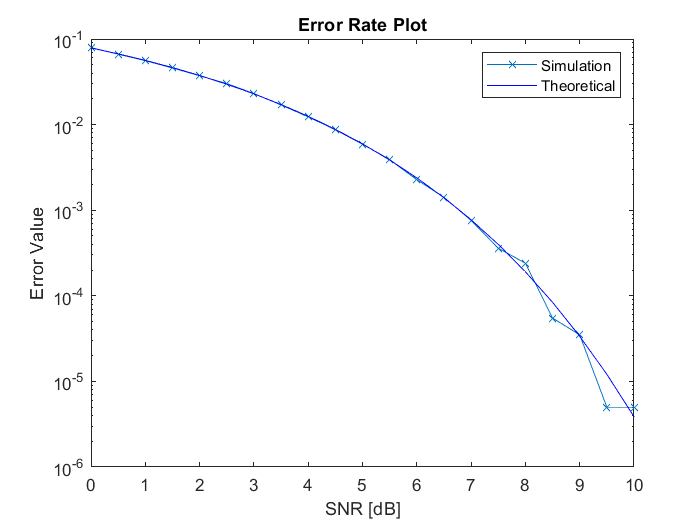

ber = berawgn(snr_values,modulation,M,'nondiff');
figure
semilogy(snr_values,ber_gray_vals,'-x'); hold on
semilogy(snr_values,ber,'b');hold off
xlabel('SNR [dB]')
ylabel('Error Value')
title('Error Rate Plot')
legend('Simulation','Theoretical')

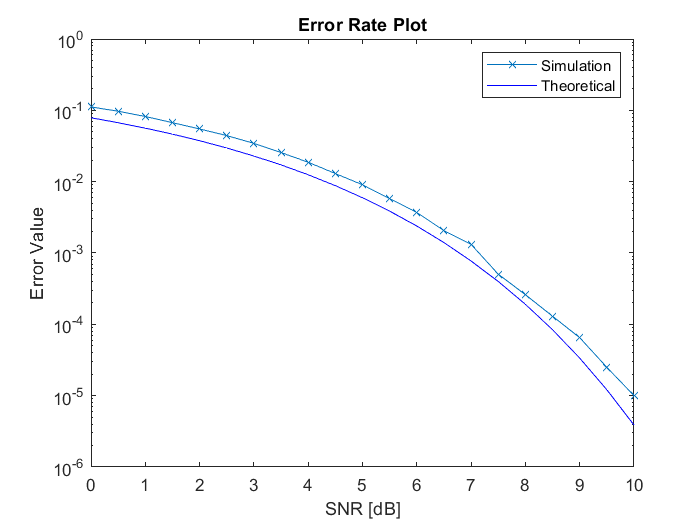

ber = berawgn(snr_values,modulation,M,'nondiff');
figure
semilogy(snr_values,ber_bin_vals,'-x'); hold on
semilogy(snr_values,ber,'b');hold off
xlabel('SNR [dB]')
ylabel('Error Value')
title('Error Rate Plot')
legend('Simulation','Theoretical')

Constellation Points Plot

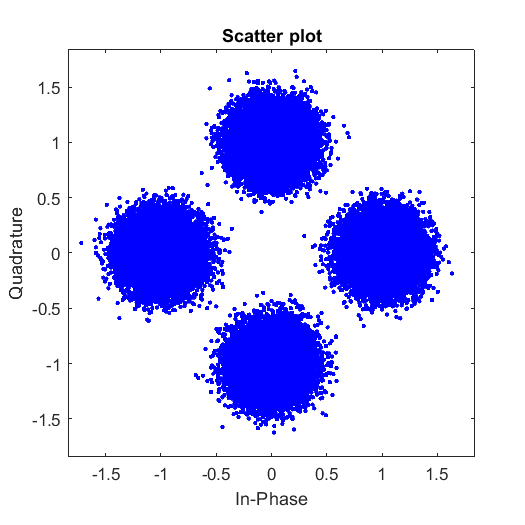

scatterplot(rx_sym_bin)

***Effect of Adding Delay & Phase***

Step 11)

delay = 0.5

delay = 0.5000

chnl_delay_in_smpl = fix(delay*smpl_per_symbl);
tx_smpl_delayed_bin = [zeros(chnl_delay_in_smpl,1);tx_smpl_bin];
tx_smpl_delayed_gray = [zeros(chnl_delay_in_smpl,1);tx_smpl_gray];
% chnl_phase_offset = 30*pi/180;
chnl_phase_offset = 0;
phase_difference = exp(1i*chnl_phase_offset);
rx_smpl_bin = tx_smpl_delayed_bin * phase_difference;
rx_smpl_gray = tx_smpl_delayed_gray * phase_difference;

%% Step 1

%M = 4;
%modulation = 'psk';
[~, Es_avg] = constellation(M, modulation);
Eb = Es_avg / log2(M) ;
N0 = Eb / (10^(10/10));
var_noise = N0;

%% Step 2

noise_smpl_bin = sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_bin),1) + 1i * sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_bin),1);
noise_smpl_gray = sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_gray),1) + 1i * sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_gray),1);
rx_smpl_bin_noise = rx_smpl_bin + noise_smpl_bin;
rx_smpl_gray_noise = rx_smpl_gray + noise_smpl_gray;

% rx_smpl_bin = rx_smpl_bin_noise;
% rx_smpl_gray = rx_smpl_gray_noise;
% modulation = 'psk';
% M = 4;
% fs = 10e6;
% smpl_per_symbl = 8;
% pulse_name = 'triangular';
rx_mode = 2;
[det_sym_idx_bin, rx_sym_bin] = pulse_demodulation(pkt_size,rx_smpl_bin, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode, 0);
[det_sym_idx_gray, rx_sym_gray] = pulse_demodulation(pkt_size,rx_smpl_gray, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode, 0);

b_binary = de2bi(0:M-1,k,'left-msb');
det_bit_bin = zeros(pkt_size,k);
for i=1:pkt_size
    det_bit_bin(i,:) = b_binary(det_sym_idx_bin(i)+1,:);
end
det_bit_bin

det_bit_bin =      0     0
     0     0
     0     0
     0     0
     0     0
     0     1
     0     1
     0     0
     0     0
     0     0



det_bit_gray = zeros(pkt_size,k);
for i=1:pkt_size
    det_bit_gray(i,:) = b_gray(det_sym_idx_gray(i)+1,:);
end
det_bit_gray

det_bit_gray =      0     0
     0     0
     0     0
     0     0
     0     0
     0     1
     0     1
     0     0
     0     0
     0     0


sym_erros_bin = ~(det_sym_idx_bin == sym_idx_bin);
ser_bin = sum(sym_erros_bin)/length(sym_idx_bin);
bit_errors = ~(det_bit_bin == b_tx);
ber_bin = sum(bit_errors,'all')/(pkt_size*k);
ser_bin

ser_bin = 0.5008

ber_bin

ber_bin = 0.3452


sym_erros_gray = ~(det_sym_idx_gray == sym_idx_gray);
ser_gray = sum(sym_erros_gray)/length(sym_idx_gray);
bit_errors = ~(det_bit_gray == b_tx);
ber_gray = sum(bit_errors,'all')/(pkt_size*k);
ser_gray

ser_gray = 0.5015

ber_gray

ber_gray = 0.2823

snr_min = 10;
snr_max = 10;
snr_step = 0.5;
snr_values = snr_min:snr_step:snr_max;
ser_bin_vals = zeros(length(snr_values),1);
ber_bin_vals = zeros(length(snr_values),1);
ser_gray_vals = zeros(length(snr_values),1);
ber_gray_vals = zeros(length(snr_values),1);

for i = 1:length(snr_values)
    temp_received_signal_bin = rx_smpl_bin;
    temp_received_signal_gray = rx_smpl_gray;
    snr_val = snr_values(i);
    N0 = Eb / (10^(snr_val/10));
    var_noise = N0;
    
    noise_smpl_bin = sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_bin),1) + 1i * sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_bin),1);
    noise_smpl_gray = sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_gray),1) + 1i * sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_gray),1);
    rx_smpl_bin_noise =  temp_received_signal_bin + noise_smpl_bin;
    rx_smpl_gray_noise =  temp_received_signal_gray + noise_smpl_gray;
    
%     rx_smpl_bin = rx_smpl_bin_noise;
%     rx_smpl_gray = rx_smpl_gray_noise;
%     modulation = 'psk';
%     M = 4;
%     fs = 10e6;
%     smpl_per_symbl = 8;
%     pulse_name = 'triangular';
%     rx_mode = 2;
    [det_sym_idx_bin, rx_sym_bin] = pulse_demodulation(pkt_size,rx_smpl_bin_noise, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode, 0);
    [det_sym_idx_gray, rx_sym_gray] = pulse_demodulation(pkt_size,rx_smpl_gray_noise, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode, 0);

    b_binary = de2bi(0:M-1,k,'left-msb');
    det_bit_bin = zeros(pkt_size,k);
    for j=1:pkt_size
        det_bit_bin(j,:) = b_binary(det_sym_idx_bin(j)+1,:);
    end
    
    det_bit_gray = zeros(pkt_size,k);
    for j=1:pkt_size
        det_bit_gray(j,:) = b_gray(det_sym_idx_gray(j)+1,:);
    end
    
    sym_erros_bin = ~(det_sym_idx_bin == sym_idx_bin);
    ser_bin = sum(sym_erros_bin)/length(sym_idx_bin);
    bit_errors = ~(det_bit_bin == b_tx);
    ber_bin = sum(bit_errors,'all')/(pkt_size*k);
   
    sym_erros_gray = ~(det_sym_idx_gray == sym_idx_gray);
    ser_gray = sum(sym_erros_gray)/length(sym_idx_gray);
    bit_errors = ~(det_bit_gray == b_tx);
    ber_gray = sum(bit_errors,'all')/(pkt_size*k);

    ser_bin_vals(i) = ser_bin;
    ser_gray_vals(i) = ser_gray;
    ber_bin_vals(i) = ber_bin;
    ber_gray_vals(i) = ber_gray;
     
end

%subplot(4,1,1);
%semilogy(snr_values,ser_bin_vals,'r'); hold on


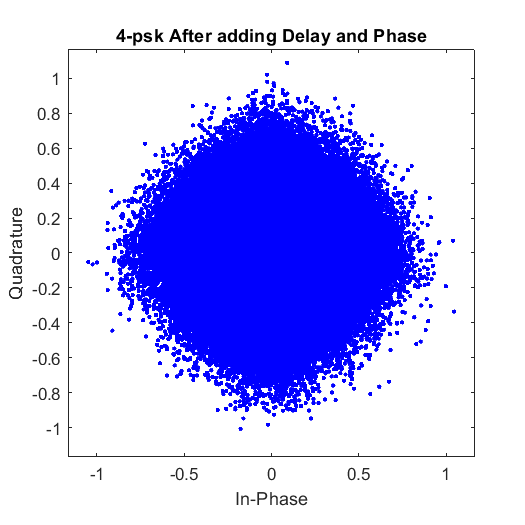

scatterplot(rx_sym_bin)
title([num2str(M) '-' modulation ' After adding Delay and Phase'])

***Adding Header***

hder_bit = repmat(reshape(de2bi(hex2dec(['1C6387FF5DA4FA325C895958DC5']'))', [], 1),1,k);

transmitive_bits = [hder_bit;b_tx]

transmitive_bits =      1     1
     0     0
     0     0
     0     0
     0     0
     0     0
     1     1
     1     1
     0     0
     1     1


%% Step 1
%k = log2(M);
b_gray = gray_code(k)

b_gray =      0     0
     0     1
     1     1
     1     0


 
sym_idx = zeros(pkt_size,1);
for i=1:length(transmitive_bits)
    temp = transmitive_bits(i,:);
    for j=0:length(b_gray)-1
        if b_gray(j+1,:) == temp
            sym_idx(i) = j;
            break;
        end
    end
end
sym_idx

sym_idx =      2
     0
     0
     0
     0
     0
     2
     2
     0
     2


%% Step 2

disp("Gray Encoding")

Gray Encoding


sym_idx_gray = sym_encoding(transmitive_bits,1)

sym_idx_gray =      2
     0
     0
     0
     0
     0
     2
     2
     0
     2



disp("Normal Encoding")

Normal Encoding


sym_idx_bin = sym_encoding(transmitive_bits,0)

sym_idx_bin =      3
     0
     0
     0
     0
     0
     3
     3
     0
     3


%% Step 3

mod_values = constellation(M,modulation);
mod_sym_bin = zeros(pkt_size,1);
for i=1:length(sym_idx)
    mod_sym_bin(i) = mod_values(sym_idx_bin(i)+1);   
end
mod_sym_bin

mod_sym_bin =   -0.0000 - 1.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
  -0.0000 - 1.0000i
  -0.0000 - 1.0000i
   1.0000 + 0.0000i
  -0.0000 - 1.0000i




mod_sym_gray = zeros(pkt_size,1);
for i=1:length(sym_idx)
    mod_sym_gray(i) = mod_values(sym_idx_gray(i)+1);   
end
mod_sym_gray

mod_sym_gray =   -1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
  -1.0000 + 0.0000i
  -1.0000 + 0.0000i
   1.0000 + 0.0000i
  -1.0000 + 0.0000i


tx_smpl_bin =pulse_modulation(sym_idx_bin, modulation, M, fs, smpl_per_symbl, pulse_name , 'kron', 0)

tx_smpl_bin =    0.0000 + 0.0000i
  -0.0000 - 0.1508i
  -0.0000 - 0.3015i
  -0.0000 - 0.4523i
  -0.0000 - 0.6030i
  -0.0000 - 0.4523i
  -0.0000 - 0.3015i
  -0.0000 - 0.1508i
   0.0000 + 0.0000i
   0.1508 + 0.0000i


tx_smpl_gray =pulse_modulation(sym_idx_gray, modulation, M, fs, smpl_per_symbl, pulse_name , 'kron', 0)

tx_smpl_gray =    0.0000 + 0.0000i
  -0.1508 + 0.0000i
  -0.3015 + 0.0000i
  -0.4523 + 0.0000i
  -0.6030 + 0.0000i
  -0.4523 + 0.0000i
  -0.3015 + 0.0000i
  -0.1508 + 0.0000i
   0.0000 + 0.0000i
   0.1508 + 0.0000i


delay = 0.5

delay = 0.5000

chnl_delay_in_smpl = fix(delay*smpl_per_symbl);
tx_smpl_delayed_bin = [zeros(chnl_delay_in_smpl,1);tx_smpl_bin];
tx_smpl_delayed_gray = [zeros(chnl_delay_in_smpl,1);tx_smpl_gray];
% chnl_phase_offset = 30*pi/180;
chnl_phase_offset = 0;
phase_difference = exp(1i*chnl_phase_offset);
rx_smpl_bin = tx_smpl_delayed_bin * phase_difference;
rx_smpl_gray = tx_smpl_delayed_gray * phase_difference;

%% Step 1

%M = 4;
%modulation = 'psk';
[~, Es_avg] = constellation(M, modulation);
Eb = Es_avg / log2(M) ;
N0 = Eb / (10^(10/10));
var_noise = N0;

%% Step 2

noise_smpl_bin = sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_bin),1) + 1i * sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_bin),1);
noise_smpl_gray = sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_gray),1) + 1i * sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_gray),1);
rx_smpl_bin_noise = rx_smpl_bin + noise_smpl_bin;
rx_smpl_gray_noise = rx_smpl_gray + noise_smpl_gray;

hdr_smpl = tx_smpl_bin(1:length(hder_bit)*smpl_per_symbl)

hdr_smpl =    0.0000 + 0.0000i
  -0.0000 - 0.1508i
  -0.0000 - 0.3015i
  -0.0000 - 0.4523i
  -0.0000 - 0.6030i
  -0.0000 - 0.4523i
  -0.0000 - 0.3015i
  -0.0000 - 0.1508i
   0.0000 + 0.0000i
   0.1508 + 0.0000i


[corr_out,lags] = xcorr(rx_smpl_bin_noise,hdr_smpl)

corr_out = 	1.0e+02 *

   0.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i


lags =      -800867     -800866     -800865     -800864     -800863     -800862     -800861     -800860     -800859     -800858     -800857     -800856     -800855     -800854     -800853     -800852     -800851     -800850     -800849     -800848     -800847     -800846     -800845     -800844     -800843     -800842     -800841     -800840     -800839     -800838     -800837     -800836     -800835     -800834     -800833     -800832     -800831     -800830     -800829     -800828     -800827     -800826     -800825     -800824     -800823     -800822     -800821     -800820     -800819     -800818


hdr_corr_max = max(abs(xcorr(hdr_smpl, hdr_smpl)))

hdr_corr_max = 108

[corr_out_rx_max, idx] = max(corr_out)

corr_out_rx_max = 1.0908e+02 + 1.4725e+00i

idx = 800872

idx_max = length(rx_smpl_bin_noise) - idx + 1 

idx_max = -3

% rx_smpl_bin = rx_smpl_bin_noise;
% rx_smpl_gray = rx_smpl_gray_noise;
% modulation = 'psk';
% M = 4;
% fs = 10e6;
% smpl_per_symbl = 8;
% pulse_name = 'triangular';
rx_mode = 2;
[det_sym_idx_bin, rx_sym_bin] = pulse_demodulation(pkt_size+length(hder_bit),rx_smpl_bin, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode, 0);
[det_sym_idx_gray, rx_sym_gray] = pulse_demodulation(pkt_size+length(hder_bit),rx_smpl_gray, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode, 0);

b_binary = de2bi(0:M-1,k,'left-msb');
det_bit_bin = zeros(pkt_size,k);
for i=1:pkt_size
    det_bit_bin(i,:) = b_binary(det_sym_idx_bin(i)+1,:);
end
det_bit_bin

det_bit_bin =      1     1
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     1     1
     0     0
     0     0



det_bit_gray = zeros(pkt_size,k);
for i=1:pkt_size
    det_bit_gray(i,:) = b_gray(det_sym_idx_gray(i)+1,:);
end
det_bit_gray

det_bit_gray =      1     1
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     1     1
     0     0
     0     0


sym_erros_bin = ~(det_sym_idx_bin == sym_idx_bin);
ser_bin = sum(sym_erros_bin)/length(sym_idx_bin);
bit_errors = ~(det_bit_bin == b_tx);
ber_bin = sum(bit_errors,'all')/(pkt_size*k);
ser_bin

ser_bin = 0.5005

ber_bin

ber_bin = 0.5003


sym_erros_gray = ~(det_sym_idx_gray == sym_idx_gray);
ser_gray = sum(sym_erros_gray)/length(sym_idx_gray);
bit_errors = ~(det_bit_gray == b_tx);
ber_gray = sum(bit_errors,'all')/(pkt_size*k);
ser_gray

ser_gray = 0.5012

ber_gray

ber_gray = 0.4992

snr_min = 10;
snr_max = 10;
snr_step = 0.5;
snr_values = snr_min:snr_step:snr_max;
ser_bin_vals = zeros(length(snr_values),1);
ber_bin_vals = zeros(length(snr_values),1);
ser_gray_vals = zeros(length(snr_values),1);
ber_gray_vals = zeros(length(snr_values),1);

for i = 1:length(snr_values)
    temp_received_signal_bin = rx_smpl_bin;
    temp_received_signal_gray = rx_smpl_gray;
    snr_val = snr_values(i);
    N0 = Eb / (10^(snr_val/10));
    var_noise = N0;
    
    noise_smpl_bin = sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_bin),1) + 1i * sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_bin),1);
    noise_smpl_gray = sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_gray),1) + 1i * sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_gray),1);
    rx_smpl_bin_noise =  temp_received_signal_bin + noise_smpl_bin;
    rx_smpl_gray_noise =  temp_received_signal_gray + noise_smpl_gray;
    
%     rx_smpl_bin = rx_smpl_bin_noise;
%     rx_smpl_gray = rx_smpl_gray_noise;
%     modulation = 'psk';
%     M = 4;
%     fs = 10e6;
%     smpl_per_symbl = 8;
%     pulse_name = 'triangular';
%     rx_mode = 2;
    [det_sym_idx_bin, rx_sym_bin] = pulse_demodulation(pkt_size+length(hder_bit),rx_smpl_bin_noise, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode, 0);
    [det_sym_idx_gray, rx_sym_gray] = pulse_demodulation(pkt_size+length(hder_bit),rx_smpl_gray_noise, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode, 0);

    b_binary = de2bi(0:M-1,k,'left-msb');
    det_bit_bin = zeros(pkt_size,k);
    for j=1:pkt_size
        det_bit_bin(j,:) = b_binary(det_sym_idx_bin(j)+1,:);
    end
    
    det_bit_gray = zeros(pkt_size,k);
    for j=1:pkt_size
        det_bit_gray(j,:) = b_gray(det_sym_idx_gray(j)+1,:);
    end
    
    sym_erros_bin = ~(det_sym_idx_bin == sym_idx_bin);
    ser_bin = sum(sym_erros_bin)/length(sym_idx_bin);
    bit_errors = ~(det_bit_bin == b_tx);
    ber_bin = sum(bit_errors,'all')/(pkt_size*k);
   
    sym_erros_gray = ~(det_sym_idx_gray == sym_idx_gray);
    ser_gray = sum(sym_erros_gray)/length(sym_idx_gray);
    bit_errors = ~(det_bit_gray == b_tx);
    ber_gray = sum(bit_errors,'all')/(pkt_size*k);

    ser_bin_vals(i) = ser_bin;
    ser_gray_vals(i) = ser_gray;
    ber_bin_vals(i) = ber_bin;
    ber_gray_vals(i) = ber_gray;
     
end